# Optimierung für Industrielogistiker

## Übungsaufgabe 7

Programmieren Sie das Nelder-Mead-Verfahren aus. Benützen Sie dafür den in der beigefügten Datei stehenden Code.

(Es steht Ihnen frei zu wählen, welche Variante des Algorithmus Sie ausporgrammieren; Sie müssen also die Parameter ALPHA, BETA und GAMMA, die in der im Skriptum vorgestellten Version des Algorithmus vorkommen, nicht benützen!)

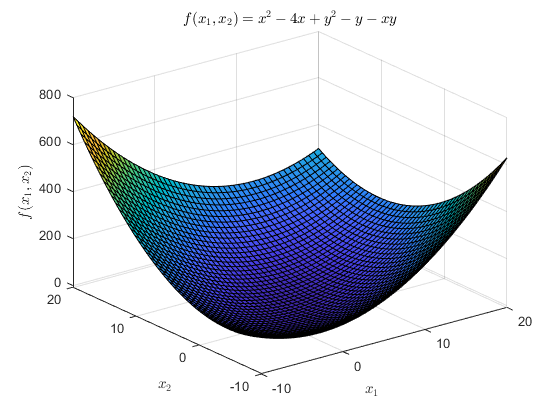

clear variablse;
clc;

f = @(x, y) x.^2 - 4 * x + y.^2 - y - x .* y;
x = linspace(-10, 20, 50);
y = linspace(-10, 20, 50);
[X, Y] = meshgrid(x, y);
Z = f(X, Y);
surf(X, Y, Z);
title('$f(x_1, x_2) = x^2 - 4 x + y^2 - y - x y$', 'interpreter', 'latex');
xlabel('$x_1$', 'interpreter', 'latex');
ylabel('$x_2$', 'interpreter', 'latex');
zlabel('$f(x_1, x_2)$', 'interpreter', 'latex');


EPSILON = 1e-3;
% MAX_NUMBER_OF_ITERATIONS = 10000;
MAX_NUMBER_OF_ITERATIONS = 100;
f = @(x) x(1).^2 - 4 * x(1) + x(2).^2 - x(2) - x(1) .* x(2);
%ALPHA = 2;
ALPHA = 1

ALPHA = 1

BETA = 0.5

BETA = 0.5000

%GAMMA = 5 / 2;
GAMMA = 2

GAMMA = 2

%X_0 = [0; 0]
X_0 = [0.5; 0.2]

X_0 =     0.5000
    0.2000


[x, numberofiterations] = neldermeadalgorithm(true, f, X_0, ALPHA, BETA, GAMMA, EPSILON, MAX_NUMBER_OF_ITERATIONS);
disp(['x:                    [', num2str(x', '%.8f '), ']']);
disp(['number of iterations: ', num2str(numberofiterations)]);

function [x, numberofiterations] = neldermeadalgorithm(MINIMIZE, f, X_0, ALPHA, BETA, GAMMA, EPSILON, MAX_NUMBER_OF_ITERATIONS)
    % best result ca 2.2, 2.2 (Z = -6)
    x_0 = X_0;
    numberofiterations = -1;
    n = 2; % Anzahl Veränderlichenchrome://vivaldi-webui/startpage?section=Speed-dials&background-color=#2f2f2f
    h = [3; 5; 8];
    x_list = createXVectorsForTriangle(n, x_0, h);
    [x_h, x_s, x_c, x_1] = defineTriangle(f, x_list);
    
    for i=0:MAX_NUMBER_OF_ITERATIONS               
        numberofiterations = numberofiterations + 1;
        x_0 = (1 + ALPHA) * x_c - ALPHA * x_h;

        y_0 = f(x_0);
        y_1 = f(x_1);
        y_s = f(x_s);
        y_h = f(x_h);
        y_c = f(x_c);
        
%         disp(['x_0:                    [', num2str(x_0', '%.8f '), ']']);
%         disp(['x_1:                    [', num2str(x_1', '%.8f '), ']']);
%         disp(['x_s:                    [', num2str(x_s', '%.8f '), ']']);
%         disp(['x_h:                    [', num2str(x_h', '%.8f '), ']']);
%         disp(['x_c:                    [', num2str(x_c', '%.8f '), ']']);
%         disp(['y_0:                    [', num2str(y_0', '%.8f '), ']']);
%         disp(['y_1:                    [', num2str(y_1', '%.8f '), ']']);
%         disp(['y_s:                    [', num2str(y_s', '%.8f '), ']']);
%         disp(['y_h:                    [', num2str(y_h', '%.8f '), ']']);
%         disp(['y_c:                    [', num2str(y_c', '%.8f '), ']']);       
    
        if y_1 <= y_0 && y_0 <= y_s
            x_h = x_0;
            continue;
        end
    
        if y_0 < y_1
            x_00 = GAMMA * x_0 + (1 - GAMMA) * x_c;
            y_00 = f(x_00);
    
            if y_00 < y_1
                x_h = x_00;
            else
                x_h = x_0;
            end
            continue;
        end
    
        if y_0 < y_h
            x_00 = BETA * x_0 + (1 - BETA) * x_c;
            y_00 = f(x_00);
            if y_00 < y_h && y_00 < y_0
                x_h = x_00;
                continue;
            elseif y_00 >= y_h || y_00 > y_0
                % Neue definition des Suchbereichs
                h = h/2;
                x_list = createXVectorsForTriangle(n, x_h, h);
    
                if cancelMethod(x_list, n, EPSILON, f)
                    x = x_00;
                    return;
                end
    
                [x_h, x_s, x_c, x_1] = defineTriangle(f, x_list);
            end
        else
            x_00 = BETA * x_h + (1 - BETA) * x_c;
            y_00 = f(x_00);
            if y_00 < y_h && y_00 < y_0
                x_h = x_00;
                continue;
            elseif y_00 >= y_h || y_00 > y_0
                % Neue definition des Suchbereichs
                h = h/2;
                x_list = createXVectorsForTriangle(n, x_h, h);
    
                if cancelMethod(x_list, n, EPSILON, f)
                    x = x_0;
                    return;
                end
    
                [x_h, x_s, x_c, x_1] = defineTriangle(f, x_list);
            end                        
        end
    end
    x = nan;
end

function [x_h, x_s, x_c, x_1] = defineTriangle(f, x_list)
    sz = size(x_list);
    len = sz(2);
    y_list = zeros(1,len);
    
    for i=1:len
        x_value = x_list(:, i);
        y_list(i) = f(x_value);
    end
    
    [~, indexes] = maxk(y_list, 2);
    [~, i_1] = min(y_list);
    
    i_h = indexes(1);
    i_s = indexes(2);
    
    x_h = x_list(:, i_h);
    x_s = x_list(:, i_s);
    x_1 = x_list(:, i_1);
           
    sum = [0; 0];
    for i=1:len 
        if i == i_h
            continue;
        end    
        x_value = x_list(:, i);
        sum = sum + x_value;
    end
        
    n = len -1;
    x_c = (1/n)*sum;
end

function [cancel] = cancelMethod(x_list, n, EPSILON, f)
    sum = 0;
    for i=1:n+1
        x_value = x_list(:, i);
        y_value = f(x_value);
        sum = sum + y_value;
    end
    s = sum/(n+1);
    
    sum = 0;
    for i=1:n+1
        x_value = x_list(:, i);
        y_value = f(x_value);
        sum = sum + ((y_value - s)^2/n)^(0.5);
    end
    
    if sum < EPSILON
        cancel = true;
    else
        cancel = false;
    end
end

function [x_list] = createXVectorsForTriangle(n, x, h)
    x_list = zeros(2, n+1);
    x_list(:, 1) = x;
    for i = 2:n+1        
        x_mi = x_list(:, i-1);
        x_i = x + h(i) * (x_mi)/norm(x_mi);
        x_list(:, i) = x_i;
    end
end

function better = isBetterThan(MINIMIZE, y1, y2 )
    if MINIMIZE
        if y1 < y2
            better = true;
            return;
        end
        better = false;
        return;
    else 
        if y1 > y2
            better = true;
            return;
        end
        better = false; 
        return;
    end
end